%Problem 3 (b)
a = 1.115 * 10^-3; %Thermal diffusivity(m^2/s)
U_l = -50; %Initial temperature (K)
U_r = 50; %Temperature at t > 0
x = linspace(-1000,1000,2000);

t = 0;
f = x./sqrt(4*a*t);
ef = erf(f);
A = (U_l/2).*(1 - ef);
B = (U_r/2).*(1 + ef);
U = A + B;

t_1 = 500000;
f_1 = x./sqrt(4*a*t_1);
ef_1 = erf(f_1);
A_1 = (U_l/2).*(1 - ef_1);
B_1 = (U_r/2).*(1 + ef_1);
U_1 = A_1 + B_1;

t_2 = 5000000;
f_2 = x./sqrt(4*a*t_2);
ef_2 = erf(f_2);
A_2 = (U_l/2).*(1 - ef_2);
B_2 = (U_r/2).*(1 + ef_2);
U_2 = A_2 + B_2;

t_3 = 500000000;
f_3 = x./sqrt(4*a*t_3);
ef_3 = erf(f_3);
A_3 = (U_l/2).*(1 - ef_3);
B_3 = (U_r/2).*(1 + ef_3);
U_3 = A_3 + B_3;

t_4 = 5000000000;
f_4 = x./sqrt(4*a*t_4);
ef_4 = erf(f_4);
A_4 = (U_l/2).*(1 - ef_4);
B_4 = (U_r/2).*(1 + ef_4);
U_4 = A_4 + B_4;

t_5 = 5*10^14;
f_5 = x./sqrt(4*a*t_5);
ef_5 = erf(f_5);
A_5 = (U_l/2).*(1 - ef_5);
B_5 = (U_r/2).*(1 + ef_5);
U_5 = A_5 + B_5;

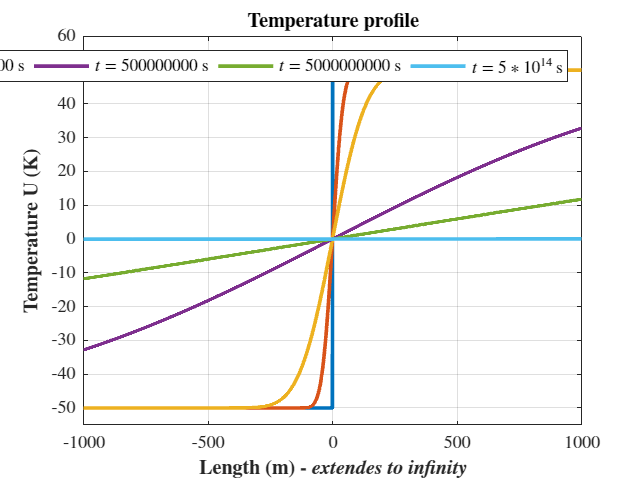

h1 = plot(x,U,'LineWidth',2);
ylabel('$\textbf{Temperature U (K)}$','Interpreter', 'latex')
xlabel('$\textbf{Length (m) - \textit{extendes to infinity}}$', 'Interpreter', 'latex')
title('$\textbf{Temperature profile}$', 'Interpreter', 'latex');
grid on
hold on
h2 = plot(x,U_1,'LineWidth',2);
h3 = plot(x,U_2,'LineWidth',2);
h4 = plot(x,U_3,'LineWidth',2);
h5 = plot(x,U_4,'LineWidth',2);
h6 = plot(x,U_5,'LineWidth',2);
legend([h1, h2, h3, h4, h5, h6], '$t = 0$ s', '$t = 500000$ s', '$t = 5000000$ s', '$t = 500000000$ s', '$t = 5000000000$ s','$t = 5 * 10^{14}$ s', 'Orientation', 'horizontal', 'Interpreter', 'latex');
ylim([-55 60])
set(gca, 'TickLabelInterpreter', 'latex');

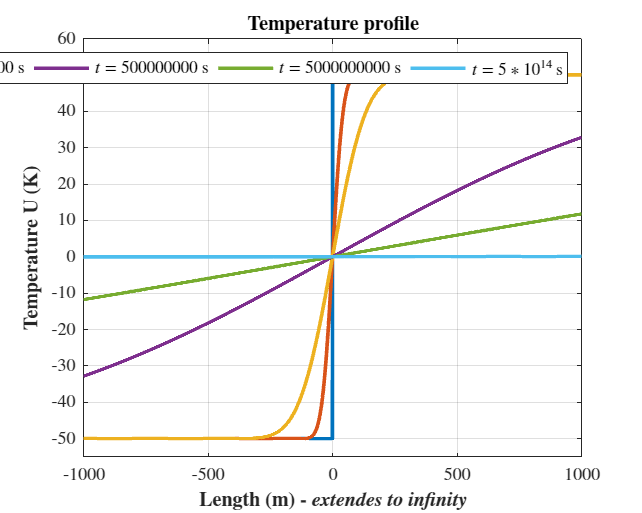

%Saving plot
outputFileName = 'Problem_3_b.png';
figureHandle = gcf;
figureWidth = 1000; % in pixels
figureHeight = 800; % in pixels
set(figureHandle, 'Position', [100, 100, figureWidth, figureHeight]); 
print(figureHandle, outputFileName, '-dpng', '-r600');